## Sprawdzian 2

Oskar Chrostowski

**Zad. 1**. Utwórz dwa wektory `a` i `b`. Jeden wypełniony liczbami $a_n =2n-1$, a drugi $b_n =2n+1$, gdzie $n=0,1,\ldotp \ldotp \ldotp ,7$. Utwórz następujące wektory: a) $a+b$, b) $a-b$ i c) $a\cdot b$.

n=0:7;
an= 2.*n -1

an =     -1     1     3     5     7     9    11    13


bn = 2.*n +1

bn =      1     3     5     7     9    11    13    15


%przykład a
suma=an+bn

suma =      0     4     8    12    16    20    24    28


%przykład b
roznica=an-bn

roznica =     -2    -2    -2    -2    -2    -2    -2    -2


%przyklad c
iloczyn=an.*bn

iloczyn =     -1     3    15    35    63    99   143   195


**Zad. 2**. Niech z=magic(5), Wykonaj następujące operacje:

a) Podziel drugą kolumnę przez $\sqrt{3}$.

z=magic(5)

z =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


z2= z(:,2)/sqrt(3)

z2 =    13.8564
    2.8868
    3.4641
    6.9282
   10.3923


b) Dodaj elementy trzeciego wiersza do elementów piątego wiersza (trzeci wiersz się nie zmienia).

z(5,:)=z(5,:) + z(3,:) 

z =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    15    24    38    22    31


c) Pomnóż elementy pierwszej kolumny przez odpowiadające im elementy piątej kolumny i wynik umieść w pierwszej kolumnie.

z(:,1)=z(:,1).*z(:,5)

z =    255    24     1     8    15
   368     5     7    14    16
    88     6    13    20    22
    30    12    19    21     3
   465    24    38    22    31


d) Znajdź maksymalną i minimalną wartość w tablicy `z`.

minimalna = min(z,[],'all')

minimalna = 1

maksymalna = max(z,[],'all')

maksymalna = 465

**Zad. 3**. Pokaż numerycznie, że następujący szereg sumuje się do podanej wartości dla $n=7$. Zakaz korzystania z pętli.


$$\sum_{k=1}^{2n-1}\cos(k\pi/n)=-1$$


n3= 7

n3 = 7

l = 2*n3 -1

l = 13

k=1:1:l

k =      1     2     3     4     5     6     7     8     9    10    11    12    13


szereg= sum(cos((k*pi)/n3))

szereg = -1.0000

**Zad. 4**. Narysuj szereg Fouriera reprezentujący sygnał piłokształtny opisany poniższym wzorem przy pomocy `plot`($\tau ,f\left(\tau \right)$). Wybierz 250 wartości $\tau$ z zadanego zakresu. Można użyć maksymalnie jedną pętlę.


$$f(\tau)=\frac{1}{2}-\frac{1}{\pi}\sum_{n=1}^{200}\frac{1}{n}\sin(2n\pi\tau),\:\:-1\le\tau\le 1$$


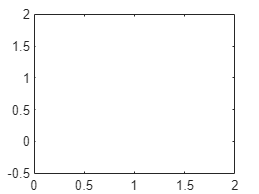

n4 = 1:1:200;
for r= linspace(-1,1,250)
    suma=sum( (1./n4).*sin(2.*n4.*pi.*r));
    y=1./2 - (1./pi).*suma;
end
plot(r,y)